# Signal Decryption Challenge

This starter code is designed for the Signal Decryption Challenge, part of the MathWorks® Hackathon. The challenge aims to help you develop essential signal processing skills while experiencing the excitement of signal decryption. 

You are encouraged to explore this repository [Signal Processing Adventures From FFT to Spectrograms and Filters](https://github.com/robert-dobre/Signal-Processing-Adventures-From-FFT-to-Spectrograms-and-Filters). It is optional to start with the five experiments in that repository, but they may help you develop the skills to tackle the hackathon. 

To save time, you can choose to begin the challenge directly by selecting one trial from the repository and completing it by following the steps outlined below. If you skip the experiments for this event, we recommend going through them after the hackathon to continue learning and to explore signal processing further.

## Clone the Repository

Before getting started, you need to clone Dr. Robert Dobre’s repository. First, check whether Git is installed by running the following command in the MATLAB Command Window:

!git --version

If Git is already installed, you can clone the repository using the command below. Replace `/path/to/the/folder` with the actual path where you want to store the repository (e.g., a local folder or a folder in your MATLAB Drive):

!git clone https://github.com/robert-dobre/Signal-Processing-Adventures-From-FFT-to-Spectrograms-and-Filters.git /path/to/the/folder

If Git is not installed, please install it first from [https://git-scm.com/downloads.](https://git-scm.com/downloads.)

Once the repository is cloned, add all its subfolders to MATLAB’s search path by running the following commands. Make sure to replace `myPath` with the actual path to the cloned repository:

myPath = fullfile(pwd, "Signal-Processing-Adventures-From-FFT-to-Spectrograms-and-Filters");
addpath(genpath(myPath)); 

## Select a Trial 

Dr. Dobre’s repository contains a total of 6 trials. Please select one to begin with. 

selectedTrialNo = "1"

## Read the Password Audio

After selecting a trial, you can read the corresponding password audio file into MATLAB using the following commands:

passwordFile = fullfile(myPath,"Trial",selectedTrialNo,strcat("password",selectedTrialNo,".wav"));
[passwordAudio, Fs] = audioread(passwordFile);

To listen to the password audio, use:

sound(passwordAudio);

The password audio is generated by the signaling system of a digital telephone dial, known as Dual-Tone Multi-Frequency (DTMF) signals. Each dialed number produces a sound composed of the sum of two sinusoidal tones, each selected from one of two non-overlapping frequency groups:

- Low-frequency group: 697 Hz, 770 Hz, 852 Hz, 941 Hz

- High-frequency group: 1209 Hz, 1336 Hz, 1477 Hz, 1633 Hz

Each pair of tones (one from the low group and one from the high group) represents a unique symbol. The standard DTMF frequency assignments for a telephone keypad are as follows:

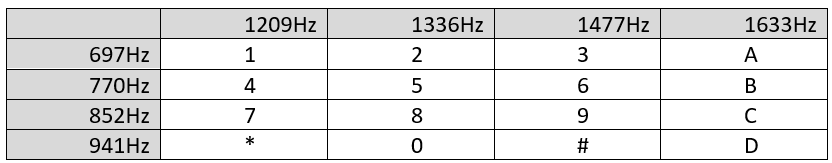

These tone pairs are used to encode the digits and symbols pressed on a telephone keypad.

## Decrypt the Password

To decrypt a hidden 11-character password from the DTMF "Password" signals, you can choose one of the following approaches:

- Use the Signal Analyzer App:Visualize the signals, extract regions of interest, and explore and analyze the password signals interactively. For more details, please refer to [1].

- Use MATLAB Code for Time-Frequency Analysis: Perform time-frequency analysis of the password signals programmatically. For more details, please refer to [2] and [3].

## Decrypt the Message

Once you have successfully decrypted the password, you can use it to unlock the corresponding “secret” audio file. To do this, unzip the ‘Secret’ folder within the same trial and enter the password when prompted.

After unlocking the audio file, you can apply signal processing techniques to reveal the hidden message. This can be done in one of two ways:

- Using the Signal Analyzer App: Explore the unlocked audio signal by applying various filtering settings to isolate or enhance the message. Refer to [1] for detailed instructions.

- Using MATLAB Code: Design and apply a notch filter to remove unwanted noise and extract the message. Refer to [4] for implementation details.

## Get your diploma for passing the Trial

Use the `Trial.mlx` script in this repository [Signal Processing Adventures From FFT to Spectrograms and Filters](https://github.com/robert-dobre/Signal-Processing-Adventures-From-FFT-to-Spectrograms-and-Filters) to check the message you decrypted and claim your membership diploma in the Fellowship of the Signal!

## **Bonus Points：Extend Your Solution to a Scalable One**

After successfully completing a trial by decrypting its password and uncovering the secret message, consider developing a scalable solution using MATLAB functions or a Simulink model. This solution should accept a password audio file as input and automatically output the decoded password.

To learn more about Simulink, refer to [5], which provides a Simulink model for generating and receiving DTMF signals. You can study this model and adapt it to automate the password decryption process.

## Resources

[1] [Signal Analysis and Visualization](https://www.mathworks.com/help/signal/signal-analyzer.html)

[2] [Practical Introduction to Time-Frequency Analysis](https://www.mathworks.com/help/signal/ug/practical-introduction-to-time-frequency-analysis.html)

[3] [DFT Estimation with the Goertzel Algorithm](https://www.mathworks.com/help/signal/ug/dft-estimation-with-the-goertzel-algorithm.html)

[4] [Design Peak and Notch Filters](https://www.mathworks.com/help/dsp/ug/design-of-peaking-and-notching-filters.html)

[5] [DTMF Generator and Receiver](https://www.mathworks.com/help/dsp/ug/dtmf-generator-and-receiver.html)

*Copyright 2025 The MathWorks, Inc.*